# 4.2 Linearization

## 3b

Testing the malformed version:

exponentionalize([0 1 1 2]', [10 5 2 1]')

ans =    10.0000
   -1.1513


Testing the corrected version:

c = exponentionalize([0 1 1 2]', [1 1 2 4]') % -0.25, 1->2

c =     0.8409
    0.6931


% against what I got
format long;
log(2) - c(2)

ans =      0


2^-0.25 - c(1)

ans =      1.110223024625157e-16


format short;

## CP3

Gode, gamle verdens befolking.

Data:

years = [1960 1970 1990 2000]'

years =         1960
        1970
        1990
        2000


populations = [3039585530 3707475887 5281653820 6079603571]'

populations = 	1.0e+09 *

    3.0396
    3.7075
    5.2817
    6.0796


Model:

format long;
c = exponentionalize(years, populations)

c =    0.000004726389209
   0.017403246298083


format short;
y = @(t) c(1).*exp(c(2).*t);

Plot:

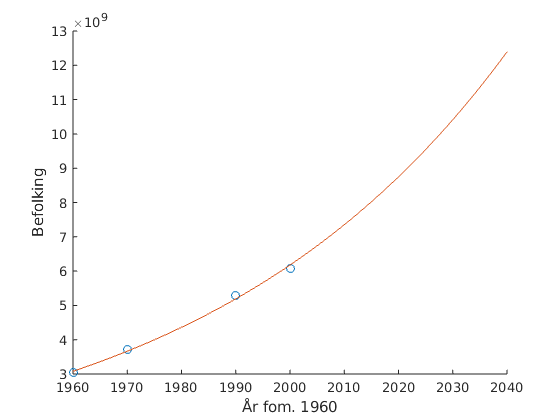

scatter(years, populations)
hold on;
range = 1960:2040;
plot(range, y(range))
xlabel('År fom. 1960')
ylabel('Befolking')
hold off;

Estimate 1980:

sprintf('Population in 1980: %e', y(1980))

ans = 'Population in 1980: 4.361486e+09'

Find error of estimate:

(compared against 4,458,003,514 from [worldometers.info](https://www.worldometers.info/world-population/world-population-by-year/))

abs(4458003514 - y(1980))

ans = 9.6518e+07

function c = exponentionalize(x, y)
y = log(y);
[n, ~] = size(x);
% let k = ln(c_1)
A = [ones(n, 1) x];
% get [k c_2]'
c = (A'*A)\(A'*y);
% then get c_1 = e^k
c(1) = exp(c(1));
end